Ξεκινάμε μετατρέποντας τις σταθερές $E_v$ και $E_c$ σε J έτσι ώστε να μπορέσουν να μπουν στους τύπους:

$N_e \left(E\right)=\frac{1}{2\pi }\cdot {\left(\frac{2m_e^* }{h}\right)}^{\frac{3}{2}} \cdot {\left(E-E_c \right)}^{\frac{1}{2}}$,


$$N_h \left(E\right)=\frac{1}{2\pi }\cdot {\left(\frac{2m_h^* }{h}\right)}^{\frac{3}{2}} \cdot {\left(E_v -E\right)}^{\frac{1}{2}}$$


χρησιμοποιώντας τα toolboxes 

u = symunit;

EcJ = double(separateUnits(unitConvert(2.2 * u.eV, u.J)))

EcJ = 3.5248e-19

EvJ = double(separateUnits(unitConvert(1 * u.eV, u.J)))

EvJ = 1.6022e-19

Αμέσως μετά θα δηλώσουμε τις σταθερές του προβλήματος:

i = 918

i = 918

m0 = 9.11 * 10^(-31)

m0 = 9.1100e-31

me = 1.09 * i / 1000 * m0

me = 9.1156e-31

mh = 1.15 * i / 100 * m0

mh = 9.6174e-30

h = 1.055 * 10^(-34)

A = 1 / (2 * pi^2);
Be = (2 * me / h)^(3 / 2);
Bh = (2 * mh / h)^(3 / 2);

Τώρα θα φτίαξω ένα matrix για να κρατήσω τις τιμές για το διάγραμμα.

matrix = [(0:0.1:4 - ); 0:0.1:4]'

matrix =      1     1
     2     2
     3     3
     4     4
     5     5
     6     6
     7     7
     8     8
     9     9
    10    10
    11    11
    12    12
    13    13
    14    14
    15    15


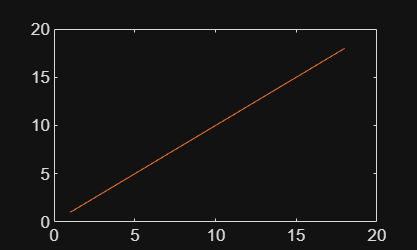


matrix(:, 1) = matrix(:, 1) .* (A * Be *